LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


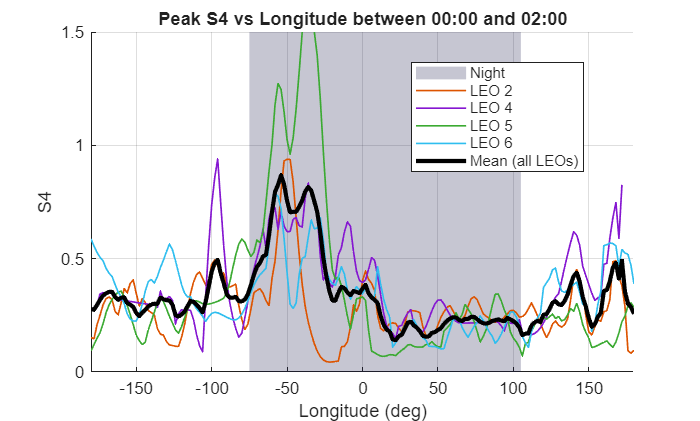

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


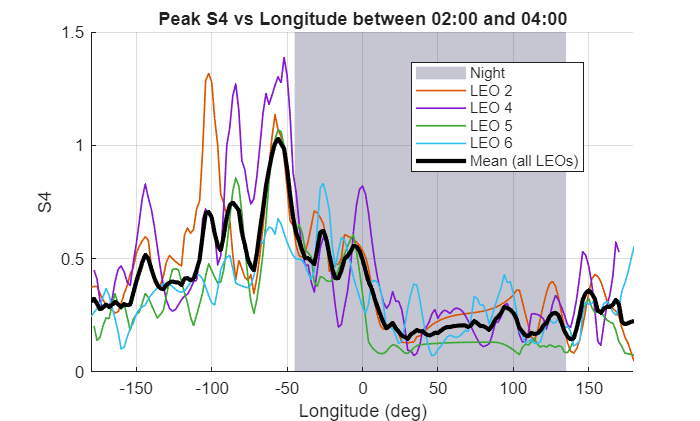

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


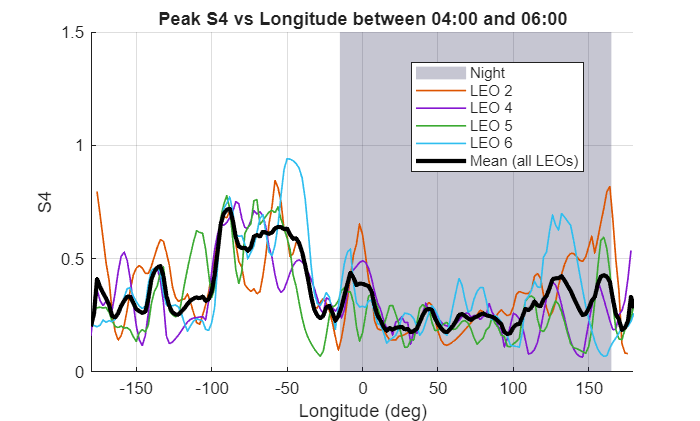

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


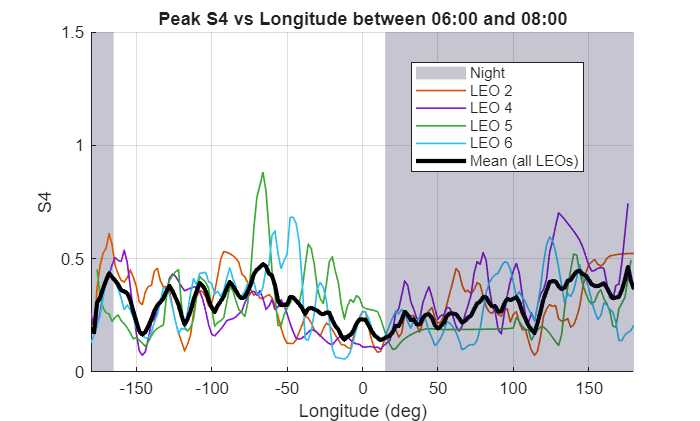

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


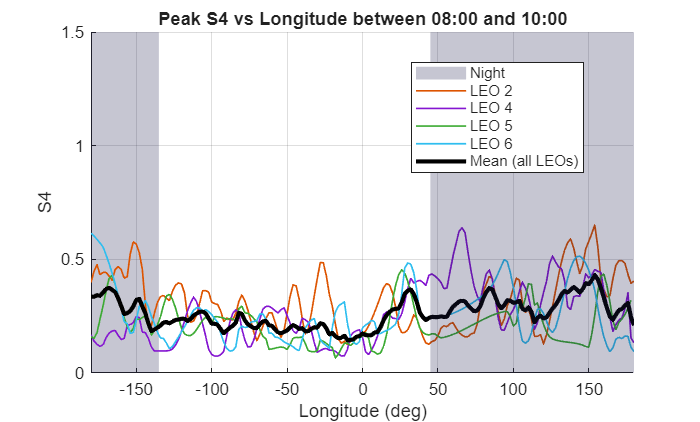

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


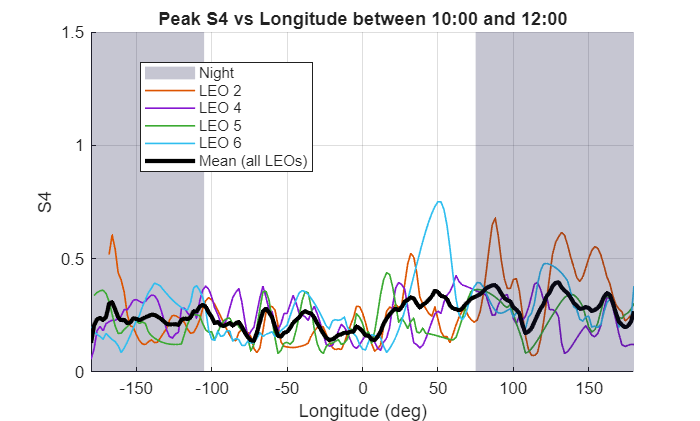

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


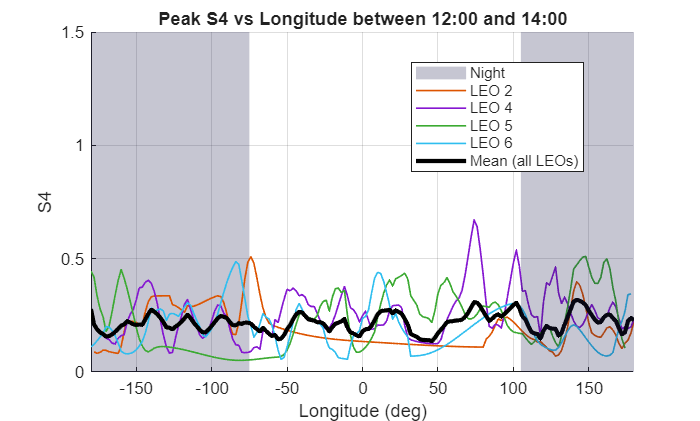

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


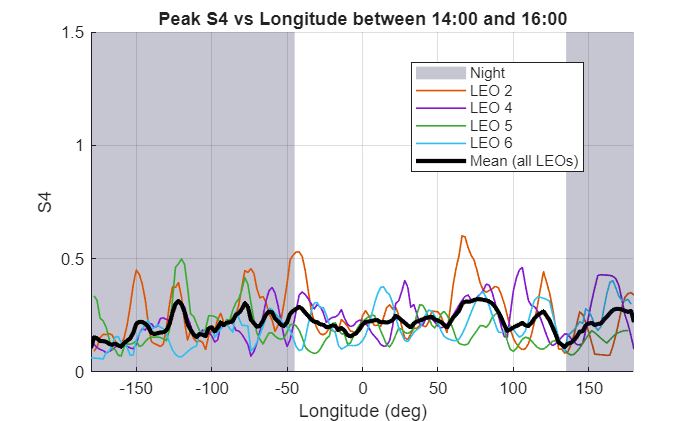

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


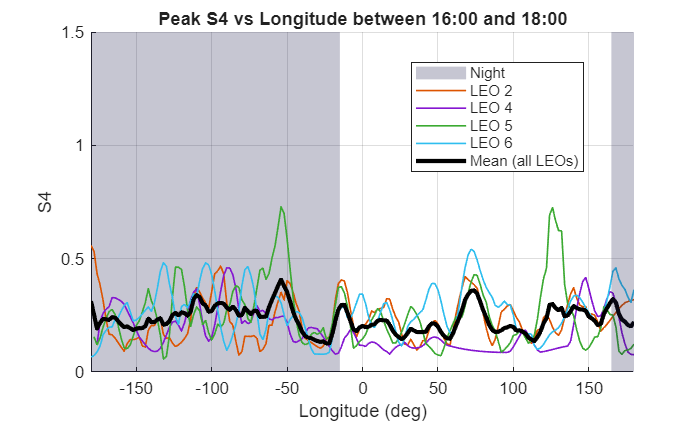

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


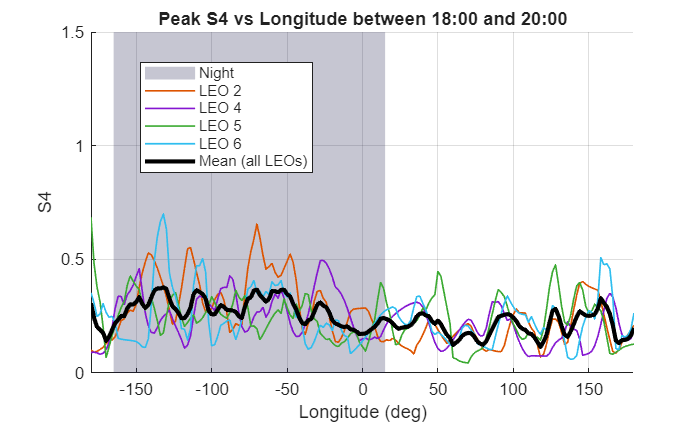

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


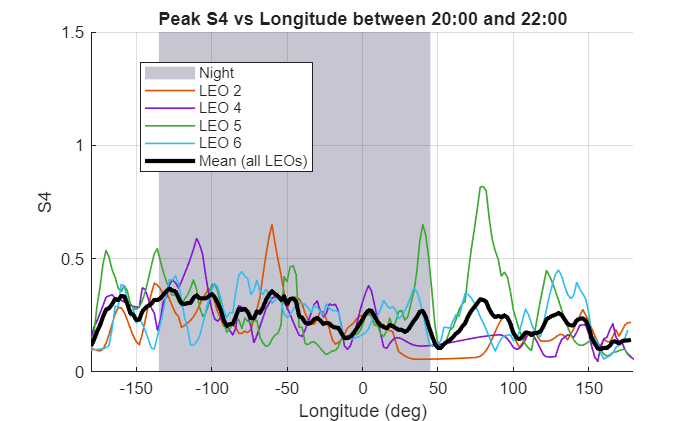

LEO 1: insufficient data points, skipping.
LEO 3: insufficient data points, skipping.


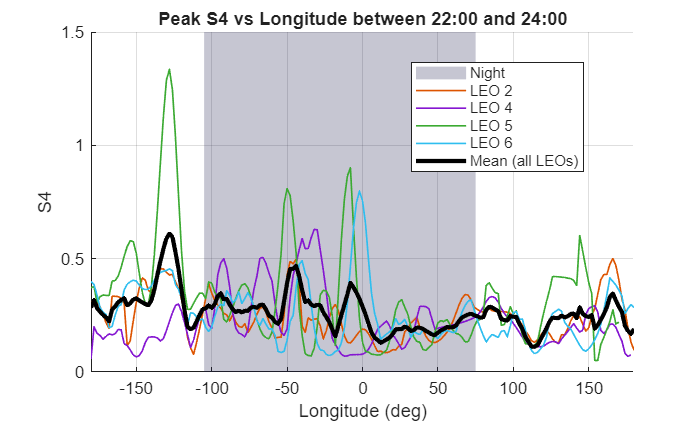

for target_hour = 1:2:23

    target_minute = 00;
    target_time = target_hour*60 + target_minute;
    time_tolerance = 60;
    colors = lines(6);

    minHour = target_hour-(time_tolerance/60);
    maxHour = target_hour+(time_tolerance/60);

    % Define common grid
    lon_grid = -180:2:180;
    all_S4_interp = NaN(6, length(lon_grid));

    figure()
    hold on

    for leo = 1:6
        peak_S4 = [];
        peak_lon = [];

        for i = 1:length(COSMIC_data)
            if COSMIC_data{i}.LEO_ID ~= leo
                continue
            end
            file_time = COSMIC_data{i}.hour*60 + COSMIC_data{i}.minute;
            if abs(file_time - target_time) > time_tolerance
                continue
            end
            elevmask = COSMIC_data{i}.elevation <0;
            S4  = COSMIC_data{i}.S4(elevmask);
            S4(S4 > 2) = NaN; 
            LON = COSMIC_data{i}.GEO_lon_LEO(elevmask);
            valid = ~isnan(S4) & ~isnan(LON);
            S4  = S4(valid);
            LON = LON(valid);
            if isempty(S4), continue; end
            [maxS4, idx_max] = max(S4);
            peak_S4(end+1,1) = maxS4;
            peak_lon(end+1,1) = LON(idx_max);
        end

        if isempty(peak_lon) || length(peak_lon) < 2
            fprintf('LEO %d: insufficient data points, skipping.\n', leo);
            continue
        end

        [peak_lon_sorted, sort_idx] = sort(peak_lon);
        peak_S4_sorted = peak_S4(sort_idx);
        [peak_lon_sorted, unique_idx] = unique(peak_lon_sorted);
        peak_S4_sorted = peak_S4_sorted(unique_idx);

        if length(peak_lon_sorted) < 2
            fprintf('LEO %d: insufficient unique longitudes after dedup, skipping.\n', leo);
            continue
        end

        % Clip lon_grid to data range for this LEO
        in_range = lon_grid >= peak_lon_sorted(1) & lon_grid <= peak_lon_sorted(end);

        S4_interp = NaN(1, length(lon_grid));
        S4_interp(in_range) = interp1(peak_lon_sorted, peak_S4_sorted, ...
                                       lon_grid(in_range), 'pchip', NaN);
        S4_interp = smoothdata(S4_interp, 'movmean', 5);

        % Store in matrix for averaging
        all_S4_interp(leo, :) = S4_interp;

        plot(lon_grid, S4_interp, ...
            'LineWidth', 1, ...
            'Color', colors(leo,:), ...
            'DisplayName', sprintf('LEO %d', leo));
    end

    % Compute and plot average across LEOs
    mean_S4 = mean(all_S4_interp, 1, 'omitnan');

    % Only plot where at least 2 LEOs contributed
    n_valid = sum(~isnan(all_S4_interp), 1);
    mean_S4(n_valid < 2) = NaN;

    plot(lon_grid, mean_S4, ...
        'k-', ...
        'LineWidth', 2.5, ...
        'DisplayName', 'Mean (all LEOs)');

    % Night shading
    lon_sub_solar    = (target_hour - 12) * 15;
    lon_night_center = lon_sub_solar + 180;
    if lon_night_center > 180
        lon_night_center = lon_night_center - 360;
    end
    
    night_left  = lon_night_center - 90;
    night_right = lon_night_center + 90;
    ylim([0,1.5])
    xlim([-180,180])
    ax    = gca; 
    y_lim = ylim(ax);     
    
    % Handle wrap around
    if night_left >= -180 && night_right <= 180

        fill([night_left night_right night_right night_left], ...
             [y_lim(1) y_lim(1) y_lim(2) y_lim(2)], ...
             [0.1 0.1 0.3], ...
             'FaceAlpha', 0.25, ...
             'EdgeColor', 'none', ...
             'DisplayName', 'Night', ...
             'HandleVisibility', 'on');
    else
        left_edge  = max(night_left,  -180);
        right_edge = min(night_right,  180);
    
        if night_left < -180
            fill([-180 (night_right) (night_right) -180], ...
                 [y_lim(1) y_lim(1) y_lim(2) y_lim(2)], ...
                 [0.1 0.1 0.3], 'FaceAlpha', 0.25, 'EdgeColor', 'none', ...
                 'DisplayName', 'Night', 'HandleVisibility', 'on');
            fill([(night_left+360) 180 180 (night_left+360)], ...
                 [y_lim(1) y_lim(1) y_lim(2) y_lim(2)], ...
                 [0.1 0.1 0.3], 'FaceAlpha', 0.25, 'EdgeColor', 'none', ...
                 'HandleVisibility', 'off');
        else
            fill([-180 (night_right-360) (night_right-360) -180], ...
                 [y_lim(1) y_lim(1) y_lim(2) y_lim(2)], ...
                 [0.1 0.1 0.3], 'FaceAlpha', 0.25, 'EdgeColor', 'none', ...
                 'DisplayName', 'Night', 'HandleVisibility', 'on');
            fill([night_left 180 180 night_left], ...
                 [y_lim(1) y_lim(1) y_lim(2) y_lim(2)], ...
                 [0.1 0.1 0.3], 'FaceAlpha', 0.25, 'EdgeColor', 'none', ...
                 'HandleVisibility', 'off');
        end
    end
    
    % Push night shading behind data
    night_patches = findobj(gca, 'Type', 'patch');
    uistack(night_patches, 'bottom');
    
    xlabel('Longitude (deg)')
    ylabel('S4')
    title(sprintf('Peak S4 vs Longitude between %02d:%02d and %02d:%02d', ...
        minHour, target_minute, maxHour, target_minute))
    legend('Location','best')
    grid on
    hold off
end